# Taller 1, punto 6: perceptron sobre las particiones de banknote

Mismo procedimiento del punto 4 pero con los datasets del punto 5. Aqui el problema ya es binario de entrada (autentico o falso), asi que no hay que armar nada.

clear; close all; clc
load banknote_splits.mat
if ~exist('informe/figuras', 'dir'), mkdir('informe/figuras'); end
if ~exist('informe/tablas', 'dir'),  mkdir('informe/tablas');  end

## Parametros

op.regla      = 3;
op.umbral     = 0;
op.salida     = [-1 1];
op.max_epocas = 200;
op.semilla    = 1;
alphas = [0.01 0.05 0.1 0.5 1];

## Entrenamiento con y sin escalar las entradas

Se prueba de las dos formas para ver si el escalado importa. La clase 0 se codifica como salida min y la clase 1 como salida max.

filas = {};
for escalar = [false true]
    for k = 1:numel(S)
        Xtr = S(k).Xtr;  Xte = S(k).Xte;
        dtr = op.salida(1) * ones(size(S(k).ytr));  dtr(S(k).ytr == 1) = op.salida(2);
        dte = op.salida(1) * ones(size(S(k).yte));  dte(S(k).yte == 1) = op.salida(2);
        if escalar
            mn = min(Xtr); mx = max(Xtr);
            Xtr = (Xtr - mn) ./ (mx - mn);
            Xte = (Xte - mn) ./ (mx - mn);
        end
        for a = alphas
            o = op; o.alpha = a;
            [w, b, info] = perceptron(Xtr, dtr, o);
            acc_tr = mean(predecir(Xtr, w, b, o.umbral, o.salida) == dtr);
            acc_te = mean(predecir(Xte, w, b, o.umbral, o.salida) == dte);
            filas(end+1, :) = {escalar, sprintf('%d-%d', round(100*S(k).p), round(100*(1-S(k).p))), ...
                a, info.epocas, info.convergio, 100*acc_tr, 100*acc_te}; %#ok<SAGROW>
        end
    end
end
R = cell2table(filas, 'VariableNames', ...
    {'Escalado', 'Particion', 'Alpha', 'Epocas', 'Convergio', 'Exact_train', 'Exact_test'});
disp(R)

    Escalado    Particion    Alpha    Epocas    Convergio    Exact_train    Exact_test
    ________    _________    _____    ______    _________    ___________    __________

     false      {'60-40'}    0.01      200        false        98.663         98.907  
     false      {'60-40'}    0.05      200        false        98.906         99.271  
     false      {'60-40'}     0.1      200        false        98.906         99.271  
     false      {'60-40'}     0.5      200        false        99.028         99.089  
     false      {'60-40'}       1      200        false        98.785         99.271  
     false      {'70-30'}    0.01      200        false        98.958         99.029  
     false      {'70-30'}    0.05      200        false        98.021         98.058  
     false      {'70-30'}     0.1      200        false        99.167         99.029  
     false      {'70-30'}     0.5      200        false        99.062         98.786  
     false      {'70-30'}       1      200

writetable(R, 'informe/tablas/perc_banknote.csv');

## Resumen por escalado y particion

Res = groupsummary(R, {'Escalado', 'Particion'}, 'mean', {'Epocas', 'Exact_train', 'Exact_test'});
disp(Res)

    Escalado    Particion    GroupCount    mean_Epocas    mean_Exact_train    mean_Exact_test
    ________    _________    __________    ___________    ________________    _______________

     false      {'60-40'}        5             200             98.858             99.162     
     false      {'70-30'}        5             200             98.583             98.592     
     false      {'80-20'}        5             200             98.707             98.394     
     false      {'90-10'}        5             200             98.785             98.394     
     true       {'60-40'}        5             200             98.615             98.069     
     true       {'70-30'}        5             200             98.875             98.447     
     true       {'80-20'}        5             200             98.852              98.54     
     true       {'90-10'}        5             200             98.462             97.664     



## Grafica: exactitud de test contra alpha, con y sin escalar

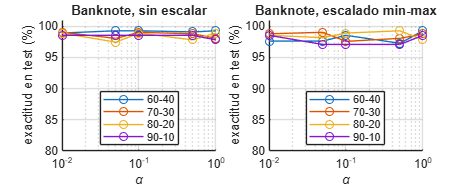

figure('Position', [100 100 950 380]);
titulos = {'sin escalar', 'escalado min-max'};
for e = 1:2
    subplot(1, 2, e); hold on
    for k = 1:numel(S)
        etiqueta = sprintf('%d-%d', round(100*S(k).p), round(100*(1-S(k).p)));
        m = R.Escalado == (e == 2) & strcmp(R.Particion, etiqueta);
        plot(R.Alpha(m), R.Exact_test(m), '-o', 'DisplayName', etiqueta);
    end
    set(gca, 'XScale', 'log'); grid on; ylim([80 101]);
    xlabel('\alpha'); ylabel('exactitud en test (%)'); title(['Banknote, ' titulos{e}]);
    legend('Location', 'best');
end
guardar_fig('perc_banknote');

## Matriz de confusion del mejor caso en test

[~, imax] = max(R.Exact_test);
fprintf('Mejor caso: escalado=%d, particion %s, alpha=%.2f, exactitud test %.2f%%\n', ...
    R.Escalado(imax), R.Particion{imax}, R.Alpha(imax), R.Exact_test(imax));

Mejor caso: escalado=0, particion 60-40, alpha=0.05, exactitud test 99.27%


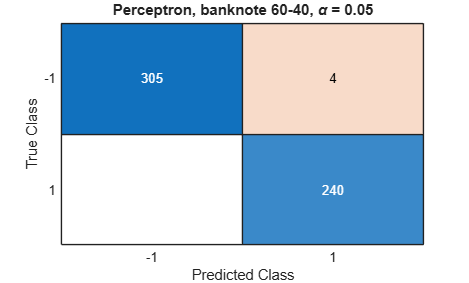

k = find(strcmp(cellfun(@(p) sprintf('%d-%d', round(100*p), round(100*(1-p))), {S.p}, 'UniformOutput', false), R.Particion{imax}));
Xtr = S(k).Xtr; Xte = S(k).Xte;
dtr = op.salida(1) * ones(size(S(k).ytr));  dtr(S(k).ytr == 1) = op.salida(2);
dte = op.salida(1) * ones(size(S(k).yte));  dte(S(k).yte == 1) = op.salida(2);
if R.Escalado(imax)
    mn = min(Xtr); mx = max(Xtr);
    Xtr = (Xtr - mn) ./ (mx - mn);  Xte = (Xte - mn) ./ (mx - mn);
end
o = op; o.alpha = R.Alpha(imax);
[w, b] = perceptron(Xtr, dtr, o);
figure; confusionchart(dte, predecir(Xte, w, b, o.umbral, o.salida));
title(sprintf('Perceptron, banknote %s, \\alpha = %.2f', R.Particion{imax}, o.alpha));
guardar_fig('perc_banknote_confusion');